Symbolic toolbar

Parachute example:

g = 9.81; m = 68.1; c = 12.5;
dt=0.1; % increment
t = 0:dt:12; %delta t = 1
v = (g*m)/c *(1-exp(-c*t/m));
plot(t,v,'go') % go =green circles
hold on % to have both graphs in same plot

Numerical method (forward Euler):

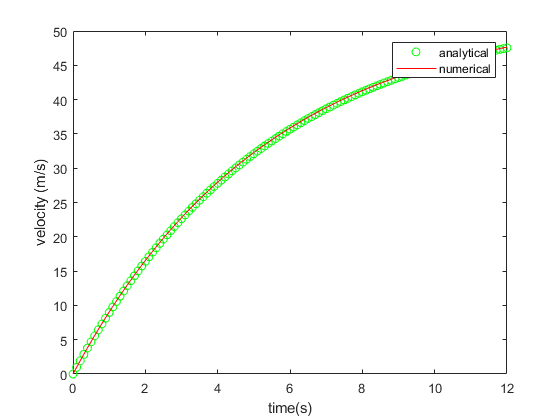

n = length(t);
v = zeros(1,n); % for performance, create v first.
v(1)=0; % initial condition is 0
for i=1:n-1
    v(i+1) = v(i)+dt*(g-c*v(i)/m);
end
plot(t,v,'-r')
legend('analytical','numerical');
xlabel('time(s)');
ylabel('velocity (m/s)')
hold off